%% ============================================================
% 4x4 RIS - REALISTIC BINARY STEERING CODEBOOK
%
% Includes:
%   1. Actual HFSS unit-cell phase/magnitude
%   2. Actual 40 mm x 40 mm unit-cell size
%   3. Actual 61 mm center-to-center pitch
%   4. 300 mm x 300 mm physical constraint
%   5. Physical aperture calculation
%   6. Edge-margin calculation
%   7. Grating-lobe check
%   8. All 16 X-direction binary patterns
%   9. Beam angle
%   10. HPBW
%   11. SLL
%   12. Target/specular comparison
%
% IMPORTANT:
% This is an ARRAY-FACTOR MODEL using HFSS unit-cell data.
% It is NOT a replacement for full-wave HFSS simulation.
%
% ============================================================

clear;
clc;
close all;

%% ============================================================
% 1. FREQUENCY AND WAVELENGTH
% ============================================================

f = 2.45e9;
c = 299792458;

lambda = c/f;
k = 2*pi/lambda;

%% ============================================================
% 2. ACTUAL PHYSICAL RIS PARAMETERS
% ============================================================

% Unit-cell physical dimensions
cellX = 40e-3;             % 40 mm
cellY = 40e-3;             % 40 mm

% Center-to-center spacing
pitchX = 61e-3;            % 61 mm
pitchY = 61e-3;            % 61 mm

% Maximum available physical area
boardX = 300e-3;           % 300 mm
boardY = 300e-3;           % 300 mm

% Array size
N = 4;

%% ============================================================
% 3. HFSS UNIT-CELL DATA
% ============================================================

phaseON  = 148.9220;
phaseOFF = -70.2555;

magON_dB  = -1.4661;
magOFF_dB = -1.3114;

magON  = 10^(magON_dB/20);
magOFF = 10^(magOFF_dB/20);

%% ============================================================
% 4. DERIVED PHYSICAL PARAMETERS
% ============================================================

pitchLambdaX = pitchX/lambda;
pitchLambdaY = pitchY/lambda;

% Center-to-center aperture
apertureX = (N-1)*pitchX;
apertureY = (N-1)*pitchY;

% Physical occupied region if the 40 mm cells are considered
% around the element centers
physicalX = apertureX + cellX;
physicalY = apertureY + cellY;

% Margin to 300 mm board
marginX = boardX - physicalX;
marginY = boardY - physicalY;

edgeMarginX = marginX/2;
edgeMarginY = marginY/2;

% Unit-cell fill ratio relative to pitch
fillFactor = ...
    (cellX*cellY)/(pitchX*pitchY);

% Number of elements
numElements = N^2;

%% ============================================================
% 5. PHASE DIFFERENCE
% ============================================================

deltaPhase = angle( ...
    exp(1j*deg2rad(phaseON-phaseOFF)));

deltaPhaseDeg = rad2deg(deltaPhase);

%% ============================================================
% 6. PRINT PHYSICAL DESIGN
% ============================================================

fprintf('\n');
fprintf('============================================================\n');

fprintf('          RIS 4x4 REAL-WORLD PHYSICAL MODEL\n');

          RIS 4x4 REAL-WORLD PHYSICAL MODEL


fprintf('============================================================\n');


fprintf('\nELECTROMAGNETIC PARAMETERS\n');


ELECTROMAGNETIC PARAMETERS


fprintf('------------------------------------------------------------\n');

------------------------------------------------------------


fprintf('Frequency                  = %.3f GHz\n',f/1e9);

Frequency                  = 2.450 GHz


fprintf('Wavelength                 = %.4f mm\n',lambda*1000);

Wavelength                 = 122.3643 mm


fprintf('Wave number                = %.4f rad/m\n',k);

Wave number                = 51.3482 rad/m



fprintf('\nUNIT CELL\n');


UNIT CELL


fprintf('------------------------------------------------------------\n');

------------------------------------------------------------


fprintf('Unit-cell X size           = %.1f mm\n',cellX*1000);

Unit-cell X size           = 40.0 mm


fprintf('Unit-cell Y size           = %.1f mm\n',cellY*1000);

Unit-cell Y size           = 40.0 mm



fprintf('\nELEMENT SPACING\n');


ELEMENT SPACING


fprintf('------------------------------------------------------------\n');

------------------------------------------------------------


fprintf('Pitch X                     = %.1f mm\n',pitchX*1000);

Pitch X                     = 61.0 mm


fprintf('Pitch Y                     = %.1f mm\n',pitchY*1000);

Pitch Y                     = 61.0 mm


fprintf('Pitch X / lambda            = %.4f lambda\n',pitchLambdaX);

Pitch X / lambda            = 0.4985 lambda


fprintf('Pitch Y / lambda            = %.4f lambda\n',pitchLambdaY);

Pitch Y / lambda            = 0.4985 lambda



fprintf('\nARRAY\n');


ARRAY


fprintf('------------------------------------------------------------\n');

------------------------------------------------------------


fprintf('Array                       = %dx%d\n',N,N);

Array                       = 4x4


fprintf('Number of elements          = %d\n',numElements);

Number of elements          = 16



fprintf('\nPHYSICAL APERTURE\n');


PHYSICAL APERTURE


fprintf('------------------------------------------------------------\n');

------------------------------------------------------------


fprintf('Center-to-center aperture   = %.1f x %.1f mm\n', ...
    apertureX*1000,apertureY*1000);

Center-to-center aperture   = 183.0 x 183.0 mm



fprintf('Cell-inclusive extent       = %.1f x %.1f mm\n', ...
    physicalX*1000,physicalY*1000);

Cell-inclusive extent       = 223.0 x 223.0 mm



fprintf('Available board             = %.1f x %.1f mm\n', ...
    boardX*1000,boardY*1000);

Available board             = 300.0 x 300.0 mm



fprintf('Remaining X margin          = %.1f mm\n',marginX*1000);

Remaining X margin          = 77.0 mm


fprintf('Remaining Y margin          = %.1f mm\n',marginY*1000);

Remaining Y margin          = 77.0 mm



fprintf('Edge margin / side          = %.1f mm\n',edgeMarginX*1000);

Edge margin / side          = 38.5 mm



fprintf('Cell fill factor            = %.2f %%\n', ...
    fillFactor*100);

Cell fill factor            = 43.00 %



%% ============================================================
% 7. HARDWARE FEASIBILITY CHECK
% ============================================================

fprintf('\n');
fprintf('============================================================\n');

fprintf('                 HARDWARE FEASIBILITY\n');

                 HARDWARE FEASIBILITY


fprintf('============================================================\n');


if physicalX <= boardX && physicalY <= boardY

    fprintf('300 mm x 300 mm constraint  = PASS\n');
    fprintf('4x4 array physically fits   = YES\n');

else

    fprintf('300 mm x 300 mm constraint  = FAIL\n');
    fprintf('4x4 array physically fits   = NO\n');

end

300 mm x 300 mm constraint  = PASS


4x4 array physically fits   = YES



if pitchX <= lambda/2 && pitchY <= lambda/2

    fprintf('Grating-lobe spacing check  = PASS\n');

else

    fprintf('Grating-lobe spacing check  = WARNING\n');

end

Grating-lobe spacing check  = PASS



%% ============================================================
% 8. ARRAY COORDINATES
% ============================================================

[xGrid,yGrid] = meshgrid( ...
    ((0:N-1)-(N-1)/2)*pitchX, ...
    ((0:N-1)-(N-1)/2)*pitchY);

x = xGrid(:);
y = yGrid(:);

%% ============================================================
% 9. THETA SCAN
% ============================================================

theta = -90:0.01:90;

%% ============================================================
% 10. ALL 16 X-DIRECTION BINARY PATTERNS
% ============================================================

numPatterns = 2^N;

allPatterns = cell(numPatterns,1);
allBeams = zeros(numPatterns,1);
allHPBW = nan(numPatterns,1);
allSLL = nan(numPatterns,1);
allTargetLevel = zeros(numPatterns,1);
allSpecularLevel = zeros(numPatterns,1);
allTargetSpecular = zeros(numPatterns,1);
allPatterns_dB = cell(numPatterns,1);

fprintf('\n');
fprintf('============================================================\n');

fprintf('             4x4 BINARY STEERING CODEBOOK\n');

             4x4 BINARY STEERING CODEBOOK


fprintf('============================================================\n');


fprintf('Number of X-direction patterns = %d\n',numPatterns);

Number of X-direction patterns = 16



%% ============================================================
% 11. EXHAUSTIVE 16-PATTERN SEARCH
% ============================================================

for p = 0:numPatterns-1

    %% Convert number to binary pattern

    bits = bitget(p,4:-1:1);

    %% Repeat across all rows

    config = repmat(bits,N,1);

    allPatterns{p+1} = config;

    %% --------------------------------------------------------
    % Assign physical phase and magnitude
    % ---------------------------------------------------------

    state = config(:);

    phase = zeros(size(state));
    magnitude = zeros(size(state));

    phase(state == 1) = deg2rad(phaseON);
    phase(state == 0) = deg2rad(phaseOFF);

    magnitude(state == 1) = magON;
    magnitude(state == 0) = magOFF;

    %% --------------------------------------------------------
    % Array factor
    % ---------------------------------------------------------

    AF = zeros(size(theta));

    for n = 1:length(theta)

        th = deg2rad(theta(n));

        % Phi = 0 degree
        steeringPhase = ...
            k*x*sin(th);

        AF(n) = sum( ...
            magnitude .* ...
            exp(1j*(phase + steeringPhase)));

    end

    %% Normalize

    P = abs(AF);

    P = P/max(P);

    PdB = 20*log10(P+1e-12);

    allPatterns_dB{p+1} = PdB;

    %% --------------------------------------------------------
    % Global maximum
    % ---------------------------------------------------------

    [~,idxPeak] = max(P);

    beamAngle = theta(idxPeak);

    allBeams(p+1) = beamAngle;

    %% --------------------------------------------------------
    % HPBW
    % ---------------------------------------------------------

    HPBW = calculateHPBW( ...
        theta,PdB,idxPeak);

    allHPBW(p+1) = HPBW;

    %% --------------------------------------------------------
    % SLL
    % ---------------------------------------------------------

    SLL = calculateSLL( ...
        theta,PdB,idxPeak,HPBW);

    allSLL(p+1) = SLL;

    %% --------------------------------------------------------
    % Specular level at theta = 0
    % ---------------------------------------------------------

    [~,idxZero] = min(abs(theta));

    specularLevel = PdB(idxZero);

    allSpecularLevel(p+1) = specularLevel;

    %% Target = actual beam
    targetLevel = 0;

    allTargetLevel(p+1) = targetLevel;

    allTargetSpecular(p+1) = ...
        targetLevel-specularLevel;

end

%% ============================================================
% 12. PRINT COMPLETE CODEBOOK
% ============================================================

fprintf('\n');
fprintf('============================================================\n');

fprintf('                COMPLETE STEERING CODEBOOK\n');

                COMPLETE STEERING CODEBOOK


fprintf('============================================================\n');


fprintf(['Pattern | Beam | HPBW | SLL | Specular | Beam-Specular\n']);

Pattern | Beam | HPBW | SLL | Specular | Beam-Specular


fprintf(['        | deg  | deg  | dB  | dB       | dB\n']);

        | deg  | deg  | dB  | dB       | dB


fprintf('------------------------------------------------------------\n');

------------------------------------------------------------



for p = 1:numPatterns

    config = allPatterns{p};

    pattern = config(1,:);

    fprintf( ...
        '%d%d%d%d   | %+6.2f | %5.2f | %5.2f | %8.2f | %+8.2f\n', ...
        pattern(1), ...
        pattern(2), ...
        pattern(3), ...
        pattern(4), ...
        allBeams(p), ...
        allHPBW(p), ...
        allSLL(p), ...
        allSpecularLevel(p), ...
        allTargetSpecular(p));

end

0000   |  +0.00 | 26.38 | -3.01 |     0.00 |    -0.00
0001   | +13.60 | 28.40 | -2.80 |    -2.60 |    +2.60
0010   | -45.39 | 46.24 | -1.32 |    -1.44 |    +1.44
0011   | +18.06 | 26.46 | -2.11 |    -8.13 |    +8.13
0100   | +45.39 | 46.24 | -1.32 |    -1.44 |    +1.44
0101   | +73.47 |   NaN |   NaN |    -9.08 |    +9.08
0110   | -37.92 | 31.18 |  0.00 |    -6.76 |    +6.76
0111   | +13.77 | 28.02 | -2.84 |    -2.75 |    +2.75
1000   | -13.60 | 28.40 | -2.80 |    -2.60 |    +2.60
1001   | -37.77 | 31.41 |  0.00 |    -6.71 |    +6.71
1010   | -73.47 |   NaN |   NaN |    -9.08 |    +9.08
1011   | -45.39 | 47.11 | -1.49 |    -1.63 |    +1.63
1100   | -18.06 | 26.46 | -2.11 |    -8.13 |    +8.13
1101   | +45.39 | 47.11 | -1.49 |    -1.63 |    +1.63
1110   | -13.77 | 28.02 | -2.84 |    -2.75 |    +2.75
1111   |  +0.00 | 26.38 | -3.01 |     0.00 |    -0.00



fprintf('============================================================\n');


%% ============================================================
% 13. UNIQUE BEAM DIRECTIONS
% ============================================================

roundedBeams = round(allBeams,1);

uniqueBeams = unique(roundedBeams);

fprintf('\n');
fprintf('============================================================\n');

fprintf('             UNIQUE ACHIEVABLE BEAM ANGLES\n');

             UNIQUE ACHIEVABLE BEAM ANGLES


fprintf('============================================================\n');


fprintf('Total binary patterns     = %d\n',numPatterns);

Total binary patterns     = 16


fprintf('Unique beam directions     = %d\n',length(uniqueBeams));

Unique beam directions     = 13



fprintf('\n');

for q = 1:length(uniqueBeams)

    angleNow = uniqueBeams(q);

    matching = find(roundedBeams == angleNow);

    fprintf('%+8.1f deg   <- %d pattern(s)\n', ...
        angleNow,length(matching));

end

   -73.5 deg   <- 1 pattern(s)
   -45.4 deg   <- 2 pattern(s)
   -37.9 deg   <- 1 pattern(s)
   -37.8 deg   <- 1 pattern(s)
   -18.1 deg   <- 1 pattern(s)
   -13.8 deg   <- 1 pattern(s)
   -13.6 deg   <- 1 pattern(s)
    +0.0 deg   <- 2 pattern(s)
   +13.6 deg   <- 1 pattern(s)
   +13.8 deg   <- 1 pattern(s)
   +18.1 deg   <- 1 pattern(s)
   +45.4 deg   <- 2 pattern(s)
   +73.5 deg   <- 1 pattern(s)


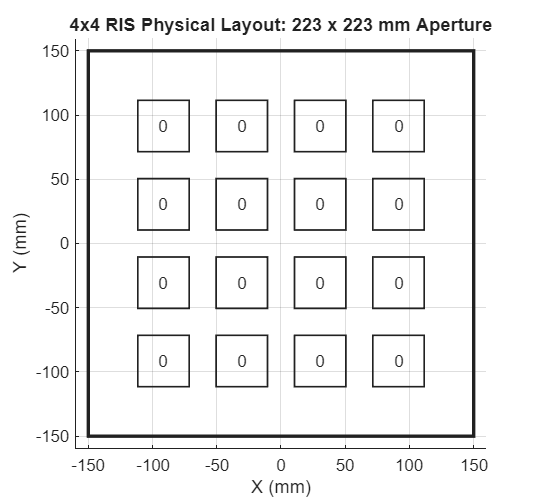


%% ============================================================
% 14. PHYSICAL CONSTRAINT PLOT
% ============================================================

figure( ...
    'Name','4x4 Physical Aperture', ...
    'Position',[100 100 700 650]);

hold on;
grid on;
axis equal;

% 300 mm board
rectangle( ...
    'Position',[ ...
        -boardX/2*1000, ...
        -boardY/2*1000, ...
        boardX*1000, ...
        boardY*1000], ...
    'LineWidth',2);

% Draw element cells
for r = 1:N

    for col = 1:N

        xc = xGrid(r,col)*1000;
        yc = yGrid(r,col)*1000;

        rectangle( ...
            'Position',[ ...
                xc-cellX*1000/2, ...
                yc-cellY*1000/2, ...
                cellX*1000, ...
                cellY*1000], ...
            'LineWidth',1);

        text( ...
            xc,yc, ...
            sprintf('%d',allPatterns{1}(r,col)), ...
            'HorizontalAlignment','center');

    end

end

xlabel('X (mm)');
ylabel('Y (mm)');

title(sprintf( ...
    '4x4 RIS Physical Layout: %.0f x %.0f mm Aperture', ...
    physicalX*1000,physicalY*1000));

xlim([-160 160]);
ylim([-160 160]);

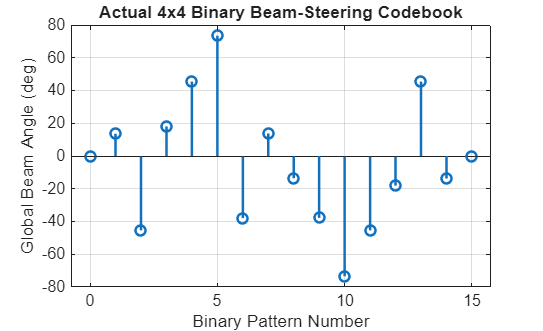


%% ============================================================
% 15. BEAM ANGLE CODEBOOK
% ============================================================

figure( ...
    'Name','4x4 Achievable Beam Angles', ...
    'Position',[150 150 900 550]);

patternNumber = 0:numPatterns-1;

stem( ...
    patternNumber, ...
    allBeams, ...
    'LineWidth',1.5);

grid on;

xlabel('Binary Pattern Number');
ylabel('Global Beam Angle (deg)');

title('Actual 4x4 Binary Beam-Steering Codebook');

yline(0,'--');

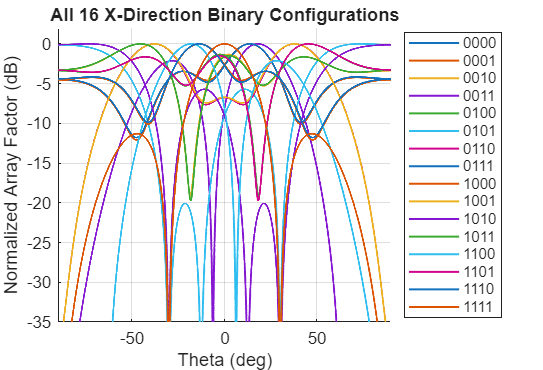


%% ============================================================
% 16. ALL RADIATION PATTERNS
% ============================================================

figure( ...
    'Name','4x4 Binary Radiation Patterns', ...
    'Position',[150 150 1100 750]);

hold on;
grid on;

for p = 1:numPatterns

    config = allPatterns{p};

    pattern = config(1,:);

    plot( ...
        theta, ...
        allPatterns_dB{p}, ...
        'LineWidth',1.2, ...
        'DisplayName',sprintf( ...
            '%d%d%d%d', ...
            pattern(1), ...
            pattern(2), ...
            pattern(3), ...
            pattern(4)));

end

xlabel('Theta (deg)');
ylabel('Normalized Array Factor (dB)');

title('All 16 X-Direction Binary Configurations');

xlim([-90 90]);
ylim([-35 2]);

legend('Location','eastoutside');


%% ============================================================
% 17. BEST STEERING STATES
% ============================================================

fprintf('\n');
fprintf('============================================================\n');

fprintf('              USEFUL STEERING STATES\n');

              USEFUL STEERING STATES


fprintf('============================================================\n');


% Find maximum positive
[positiveBeam,idxPositive] = max(allBeams);

configPositive = allPatterns{idxPositive};

fprintf('\nMaximum positive steering:\n');


Maximum positive steering:



fprintf('Pattern = %d%d%d%d\n', ...
    configPositive(1,1), ...
    configPositive(1,2), ...
    configPositive(1,3), ...
    configPositive(1,4));

Pattern = 0101



fprintf('Beam    = %+8.2f deg\n',positiveBeam);

Beam    =   +73.47 deg



% Find maximum negative
[negativeBeam,idxNegative] = min(allBeams);

configNegative = allPatterns{idxNegative};

fprintf('\nMaximum negative steering:\n');


Maximum negative steering:



fprintf('Pattern = %d%d%d%d\n', ...
    configNegative(1,1), ...
    configNegative(1,2), ...
    configNegative(1,3), ...
    configNegative(1,4));

Pattern = 1010



fprintf('Beam    = %+8.2f deg\n',negativeBeam);

Beam    =   -73.47 deg



%% ============================================================
% 18. TARGET ANGLE FEASIBILITY
% ============================================================

targetAngles = [0 5 10 15 20 25 30 35 40];

fprintf('\n');
fprintf('============================================================\n');

fprintf('             TARGET ANGLE FEASIBILITY\n');

             TARGET ANGLE FEASIBILITY


fprintf('============================================================\n');


fprintf(['Target | Closest Beam | Error | Pattern | HPBW | SLL\n']);

Target | Closest Beam | Error | Pattern | HPBW | SLL


fprintf('------------------------------------------------------------\n');

------------------------------------------------------------



for t = 1:length(targetAngles)

    target = targetAngles(t);

    [~,idxClosest] = ...
        min(abs(allBeams-target));

    config = allPatterns{idxClosest};

    pattern = config(1,:);

    fprintf( ...
        '%5.1f | %+11.2f | %+5.2f | %d%d%d%d | %5.2f | %5.2f\n', ...
        target, ...
        allBeams(idxClosest), ...
        allBeams(idxClosest)-target, ...
        pattern(1), ...
        pattern(2), ...
        pattern(3), ...
        pattern(4), ...
        allHPBW(idxClosest), ...
        allSLL(idxClosest));

end

  0.0 |       +0.00 | +0.00 | 0000 | 26.38 | -3.01
  5.0 |       +0.00 | -5.00 | 0000 | 26.38 | -3.01
 10.0 |      +13.60 | +3.60 | 0001 | 28.40 | -2.80
 15.0 |      +13.77 | -1.23 | 0111 | 28.02 | -2.84
 20.0 |      +18.06 | -1.94 | 0011 | 26.46 | -2.11
 25.0 |      +18.06 | -6.94 | 0011 | 26.46 | -2.11
 30.0 |      +18.06 | -11.94 | 0011 | 26.46 | -2.11
 35.0 |      +45.39 | +10.39 | 0100 | 46.24 | -1.32
 40.0 |      +45.39 | +5.39 | 0100 | 46.24 | -1.32



%% ============================================================
% 19. GRATING-LOBE / SPACING INFORMATION
% ============================================================

fprintf('\n');
fprintf('============================================================\n');

fprintf('              SPACING / GRATING-LOBE CHECK\n');

              SPACING / GRATING-LOBE CHECK


fprintf('============================================================\n');


fprintf('d/lambda = %.4f\n',pitchLambdaX);

d/lambda = 0.4985



if pitchLambdaX <= 0.5

    fprintf('PASS: d <= lambda/2.\n');
    fprintf('No conventional grating lobes expected for broadside\n');
    fprintf('and normal scanning under the ideal array-factor model.\n');

else

    fprintf('WARNING: d > lambda/2.\n');
    fprintf('Grating-lobe risk exists.\n');

end

PASS: d <= lambda/2.


No conventional grating lobes expected for broadside


and normal scanning under the ideal array-factor model.



%% ============================================================
% 20. FINAL ENGINEERING SUMMARY
% ============================================================

fprintf('\n');
fprintf('============================================================\n');

fprintf('                 ENGINEERING SUMMARY\n');

                 ENGINEERING SUMMARY


fprintf('============================================================\n');


fprintf('\n');
fprintf('Frequency              : %.2f GHz\n',f/1e9);

Frequency              : 2.45 GHz


fprintf('Wavelength             : %.2f mm\n',lambda*1000);

Wavelength             : 122.36 mm


fprintf('Unit cell              : %.0f x %.0f mm\n', ...
    cellX*1000,cellY*1000);

Unit cell              : 40 x 40 mm


fprintf('Element pitch          : %.0f mm\n',pitchX*1000);

Element pitch          : 61 mm


fprintf('Pitch/lambda           : %.4f\n',pitchLambdaX);

Pitch/lambda           : 0.4985


fprintf('Array                  : %dx%d\n',N,N);

Array                  : 4x4


fprintf('Elements               : %d\n',numElements);

Elements               : 16



fprintf('\n');
fprintf('Center-to-center aperture : %.1f x %.1f mm\n', ...
    apertureX*1000,apertureY*1000);

Center-to-center aperture : 183.0 x 183.0 mm



fprintf('Cell-inclusive extent     : %.1f x %.1f mm\n', ...
    physicalX*1000,physicalY*1000);

Cell-inclusive extent     : 223.0 x 223.0 mm



fprintf('Available area            : 300 x 300 mm\n');

Available area            : 300 x 300 mm



fprintf('\n');
fprintf('HFSS ON phase          : %+8.3f deg\n',phaseON);

HFSS ON phase          : +148.922 deg


fprintf('HFSS OFF phase         : %+8.3f deg\n',phaseOFF);

HFSS OFF phase         :  -70.255 deg


fprintf('Phase separation       : %8.3f deg\n',abs(deltaPhaseDeg));

Phase separation       :  140.823 deg



fprintf('\n');
fprintf(['CONCLUSION:\n' ...
         'The 4x4 RIS is physically realizable within the\n' ...
         '300 x 300 mm constraint, but its 1-bit phase states\n' ...
         'provide a discrete rather than continuously tunable\n' ...
         'beam-steering response.\n']);

CONCLUSION:
The 4x4 RIS is physically realizable within the
300 x 300 mm constraint, but its 1-bit phase states
provide a discrete rather than continuously tunable
beam-steering response.



fprintf('\n');
fprintf(['The achievable beam directions should be selected from\n' ...
         'the calculated binary codebook and then validated\n' ...
         'individually in HFSS.\n']);

The achievable beam directions should be selected from
the calculated binary codebook and then validated
individually in HFSS.



fprintf('============================================================\n');


%% ============================================================
% HELPER FUNCTION: HPBW
% ============================================================

function HPBW = calculateHPBW(theta,PdB,idxPeak)

    level = -3;

    left = idxPeak;
    right = idxPeak;

    while left > 1 && PdB(left) >= level
        left = left-1;
    end

    while right < length(PdB) && PdB(right) >= level
        right = right+1;
    end

    if left == 1 || right == length(PdB)

        HPBW = NaN;

    else

        HPBW = theta(right)-theta(left);

    end

end

%% ============================================================
% HELPER FUNCTION: SLL
% ============================================================

function SLL = calculateSLL(theta,PdB,idxPeak,HPBW)

    if isnan(HPBW)

        SLL = NaN;
        return;

    end

    peakAngle = theta(idxPeak);

    exclusion = ...
        abs(theta-peakAngle) <= HPBW/2;

    sidelobes = PdB(~exclusion);

    if isempty(sidelobes)

        SLL = NaN;

    else

        SLL = max(sidelobes);

    end

end